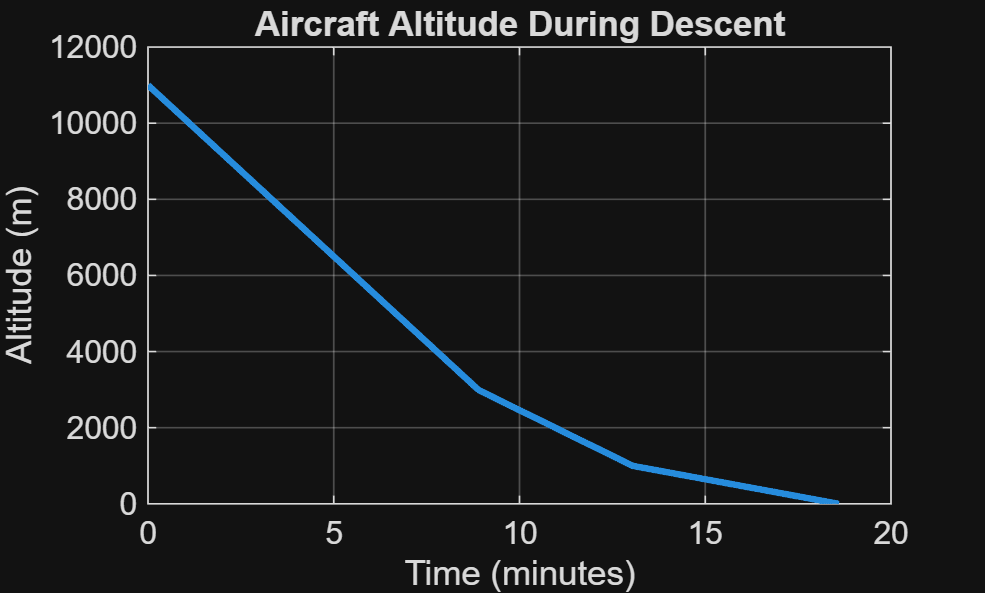

clc;
clear;
close all;

%% Simulation Parameters

dt = 1;                   % Time step (s)
t_end = 2000;             % Maximum simulation time
t = 0:dt:t_end;

%% Aircraft Parameters

h0 = 11000;               % Initial altitude (m)
hf = 0;                   % Landing altitude (m)

V0 = 250;                 % Initial speed (m/s)
Vmin = 70;                % Minimum approach speed (m/s)

max_descent = 15;         % Maximum descent rate (m/s)

%% Initialize Arrays

h = zeros(size(t));
V = zeros(size(t));
Vv = zeros(size(t));

h(1) = h0;
V(1) = V0;

%% Simulation Loop

for i = 2:length(t)

    % ----- Phase 1: Steady Descent -----
    if h(i-1) > 3000

        Vv(i) = -max_descent;

        % Gradual speed reduction
        V(i) = V(i-1) - 0.03;

    % ----- Phase 2: Leveling -----
    elseif h(i-1) > 1000

        Vv(i) = -8;

        % Faster deceleration
        V(i) = V(i-1) - 0.05;

    % ----- Phase 3: Final Approach -----
    else

        Vv(i) = -3;

        % Approach speed stabilization
        V(i) = V(i-1) - 0.02;

    end

    % Enforce minimum speed constraint
    if V(i) < Vmin
        V(i) = Vmin;
    end

    % Update altitude
    h(i) = h(i-1) + Vv(i)*dt;

    % Prevent negative altitude
    if h(i) <= hf
        h(i) = hf;

        % Stop simulation at landing
        h = h(1:i);
        V = V(1:i);
        Vv = Vv(1:i);
        t = t(1:i);

        break;
    end
end

%% Plot Altitude

figure;
plot(t/60, h, 'LineWidth',2);

xlabel('Time (minutes)');
ylabel('Altitude (m)');
title('Aircraft Altitude During Descent');
grid on;

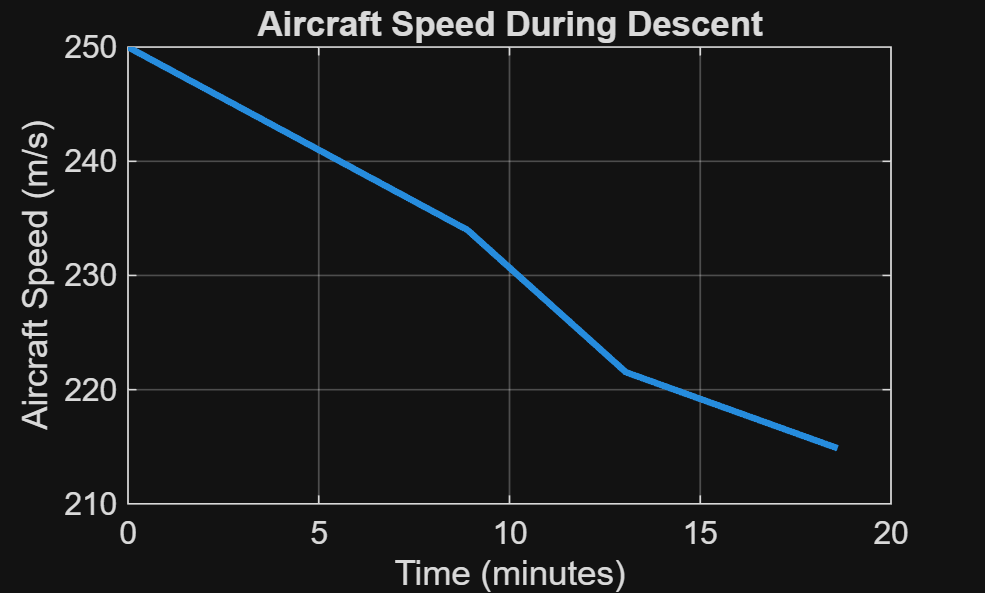


%% Plot Aircraft Speed

figure;
plot(t/60, V, 'LineWidth',2);

xlabel('Time (minutes)');
ylabel('Aircraft Speed (m/s)');
title('Aircraft Speed During Descent');
grid on;

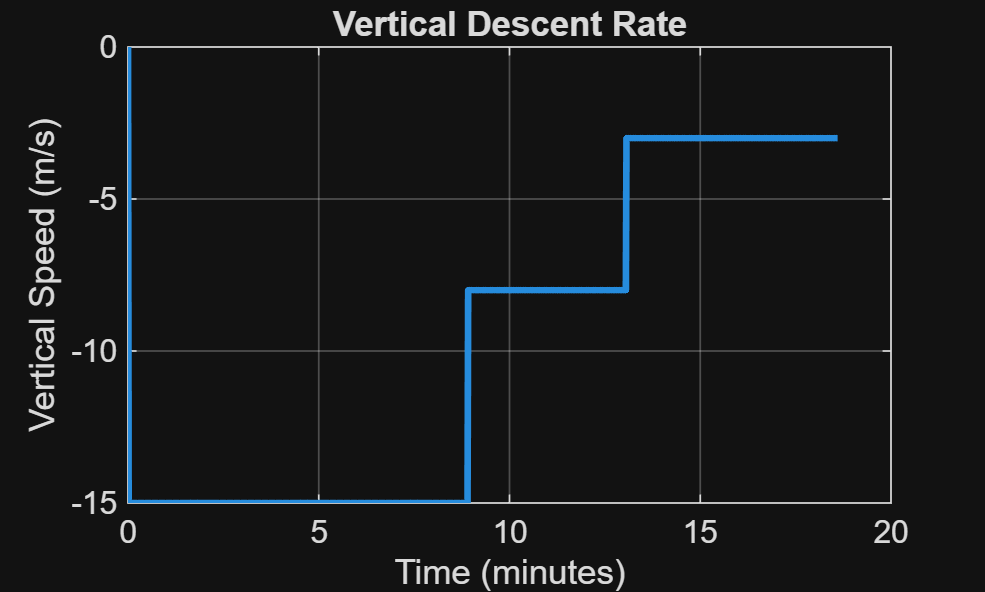


%% Plot Vertical Speed

figure;
plot(t/60, Vv, 'LineWidth',2);

xlabel('Time (minutes)');
ylabel('Vertical Speed (m/s)');
title('Vertical Descent Rate');
grid on;